% import confusionmatStats function
addpath('C:\Users\Diego\Desktop\matprojects\funciones');

stroke=readtable('C:\Users\Diego\OneDrive - Universidad Autonoma de Madrid\metodologia\TECNOLOGIA DEL CONOCIMIENTO\datos_TC\stroke2.csv');

stroke = 43400×16 table
    Var1     id        gender      age    hypertension    heart_disease    ever_married        work_type        Residence_type    avg_glucose_level    bmi       smoking_status       stroke     age_cat        glucose_cat           bmi_cat    
    ____    _____    __________    ___    ____________    _____________    ____________    _________________    ______________    _________________    ____    ___________________    ______    __________    __________


% normalize quantitative variables
stroke(:,["age","avg_glucose_level"])=normalize(stroke(:,["age","avg_glucose_level"]),'range');

% features of the best models
featQDA=stroke.age;
feattree=stroke(:,["age_cat","hypertension","heart_disease","bmi_cat"]);
featSVM=stroke(:,["age","avg_glucose_level","hypertension", ...
    "smoking_status","heart_disease"]);

% target
group=stroke.stroke;

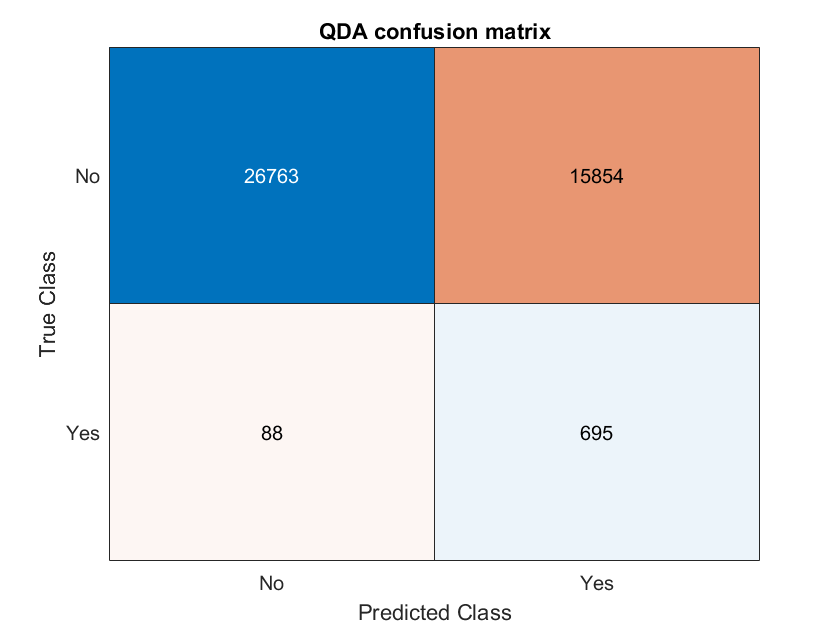

qda=fitcdiscr(featQDA,group, ...
    'DiscrimType','quadratic', ...
    'CrossVal','on', ...
    'Cost',[0 1;70 0]);

% predictions ............
[predsQDA, postprQDA]=kfoldPredict(qda);

% assessment ..............
confusionchart(group,predsQDA);
title('QDA confusion matrix')

c=confusionmatStats(group,predsQDA);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity     Fscore 
                 ________    ___________    ___________    ________
    Class No     0.63267       0.62799        0.88761       0.77051
    Class Yes    0.63267       0.88761        0.62799      0.080198


% ROC .................
[FPRqda, TPRqda, ~, AUCqda]=perfcurve(group,postprQDA(:,2),'Yes');
AUCqda

AUCqda = 0.8393

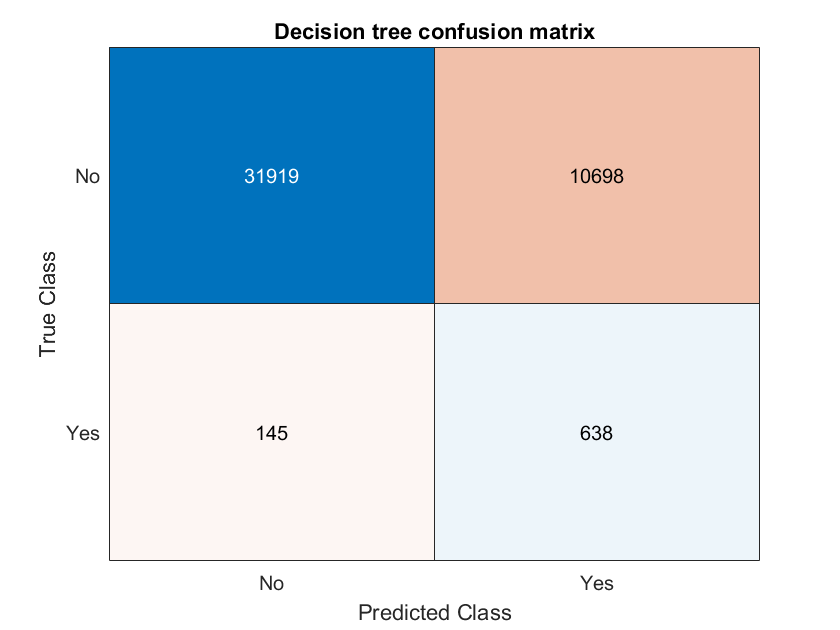

tree=fitctree(feattree,group, ...
    'CategoricalPredictors','all', ...
    'SplitCriterion','deviance', ...
    'MinLeafSize',200, 'MinParentSize',230, ...
    'CrossVal','on', ... 
    'Cost',[0 1;70 0]);

% predictions ............
[predstree, postprtree]=kfoldPredict(tree);

% assessment ..............
confusionchart(group,predstree);
title('Decision tree confusion matrix')

c=confusionmatStats(group,predstree);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity    Fscore 
                 ________    ___________    ___________    _______
    Class No     0.75016       0.74897        0.81481      0.85481
    Class Yes    0.75016       0.81481        0.74897      0.10529


% ROC .................
[FPRtree, TPRtree, ~, AUCtree]=perfcurve(group,postprtree(:,2),'Yes');
AUCtree

AUCtree = 0.8121

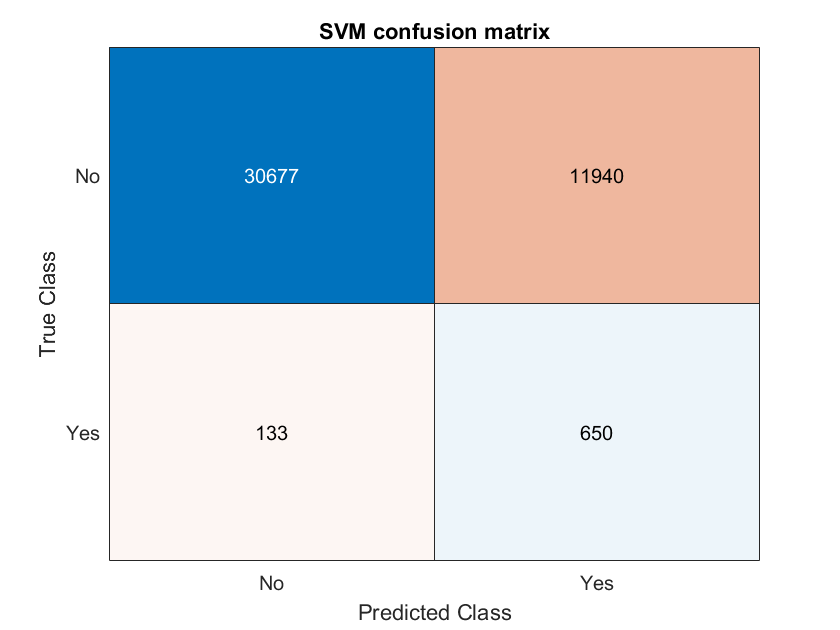

SVM=fitcsvm(featSVM,group, ...
    'CategoricalPredictors',{'hypertension','smoking_status','heart_disease'}, ...
    'BoxConstraint', 0.24, ...
    'KernelFunction','linear', ...
    'CrossVal','on', ...
    'Cost',[0 1;55 0]);

% predictions ............
[predsSVM, postprSVM]=kfoldPredict(SVM);

% assessment ..............
confusionchart(group,predsSVM);
title('SVM confusion matrix')

c=confusionmatStats(group,predsSVM);
accuracy=c.accuracy; sensitivity=c.sensitivity; specificity=c.specificity; Fscore=c.Fscore;
table(accuracy,sensitivity,specificity,Fscore,'RowNames',{'Class No','Class Yes'})

ans = 2×4 table
                 accuracy    sensitivity    specificity     Fscore 
                 ________    ___________    ___________    ________
    Class No     0.72182       0.71983        0.83014       0.83558
    Class Yes    0.72182       0.83014        0.71983      0.097211


% ROC .................
[FPRSVM, TPRSVM, ~, AUCSVM]=perfcurve(group,postprSVM(:,2),'Yes');
AUCSVM

AUCSVM = 0.8509

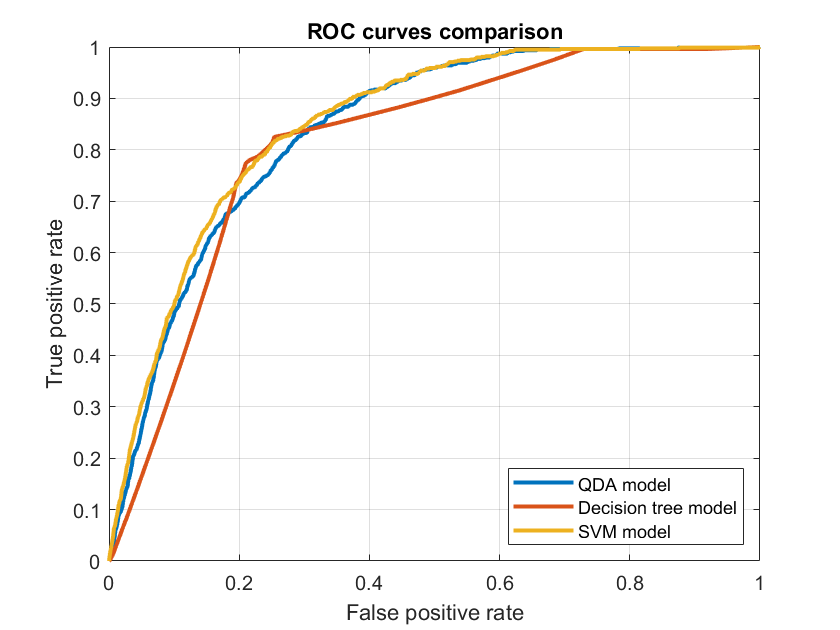

plot(FPRqda,TPRqda,'LineWidth',2);
hold on
grid on
plot(FPRtree,TPRtree,'LineWidth',2);
plot(FPRSVM,TPRSVM,'LineWidth',2);
title('ROC curves comparison');
xlabel('False positive rate');
ylabel('True positive rate'); 
legend({'QDA model' 'Decision tree model' 'SVM model'},'Location','southeast');
hold off

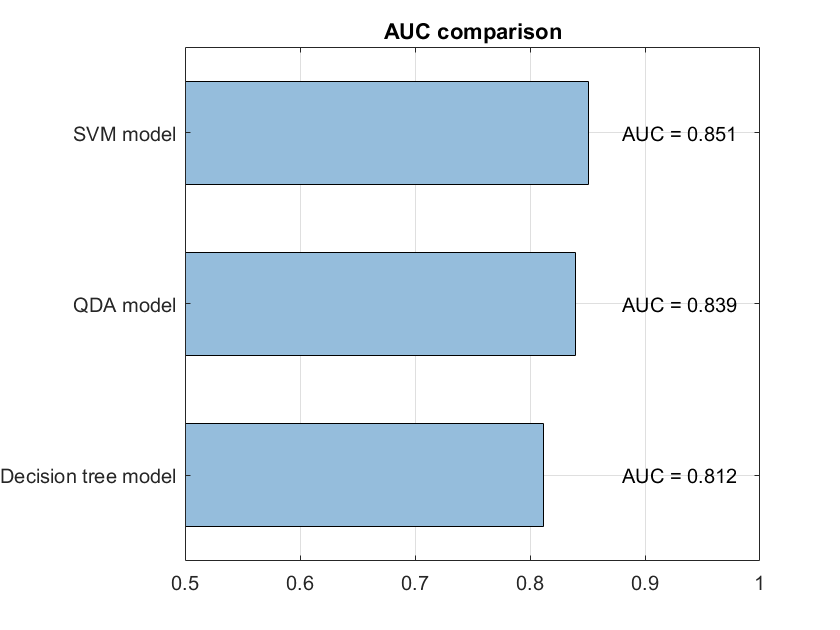

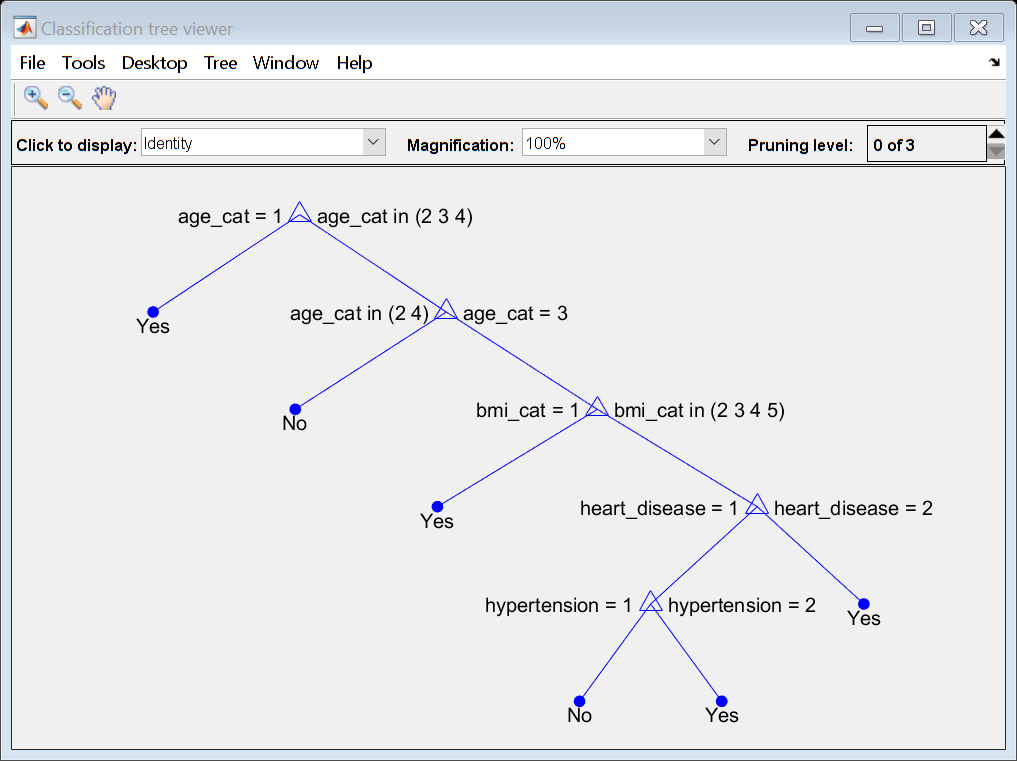

models=categorical({'QDA model' 'Decision tree model' 'SVM model'});

barh(models,[AUCqda AUCtree AUCSVM],.6,'FaceColor','#95bddc')
title('AUC comparison')
grid on
text(.88,3,['AUC = ' num2str(round(AUCSVM,3))]);
text(.88,2,['AUC = ' num2str(round(AUCqda,3))]);
text(.88,1,['AUC = ' num2str(round(AUCtree,3))]);
xlim([0.5 1])